# Atomically resolve a metabolic reconstruction

## Author(s): **Hulda S. Haraldsdóttir and German A. Preciat Gonzalez, **Systems Biochemistry Group, University of Luxembourg.

## Reviewer(s): 

## INTRODUCTION

Genome-scale metabolic network reconstructions have become a relevant tool in modern biology to study the metabolic pathways of biological systems *in silico*. However, a more detailed representation at the underlying level of atom mappings opens the possibility for a broader range of biological, biomedical and biotechnological applications than with stoichiometry alone. 

A set of atom mappings represents the mechanism of each chemical reaction in a metabolic network, each of which relates an atom in a substrate metabolite to an atom of the same element in a product metabolite. To atom map reactions in a metabolic network reconstruction, one requires chemical structures in a data file format (SMILES, MDL MOL, InChIs), reaction stoichiometries, and an atom mapping algorithm.

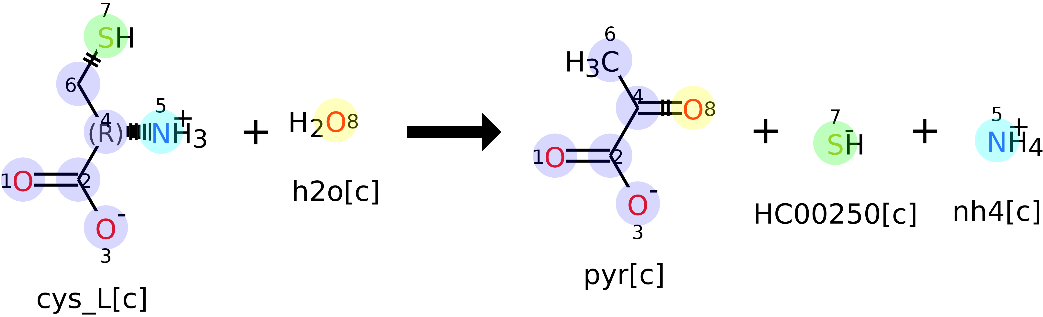

Figure 1. Set of atom mappings for reaction L-Cysteine L-Homocysteine-Lyase (VMH ID: r0193).

Metabolites chemical structures can be obtained by different approaches such as draw them based on the literature using chemoinformatic software, or obtain them from metabolic databases either manually or using a computational software as suggested in [1]. Here we recommend downloading the metabolites structures in MDL MOL format for the latest human metabolic reconstruction Recon 3 [2] via the Virtual Metabolic Human database (VMH, [http://vmh.life](http://vmh.life)). Chemical structures and reaction stoichiometries from COBRA models are used to generate an MDL RXN file, which contains the information of a chemical reaction. Atom mapped reactions from Recon 3 can also be found in the VMH database in MDL RXN format. However, here we will atom map the chemical reactions using the Reaction Decoder Tool (RDT) algorithm [3], which was selected after comparing the performance of recently published algorithms [4]. However, despite its good performance (accuracy and availability) RDT algorithm does not atom map hydrogen atoms.

In this tutorial, we will identify the conserved moieties using atom mapping data for the dopamine synthesis network (DAS) extracted from Recon 3 [2] (Figure 2). Section 1 covers the obtention of atom mapping data. Section 2 Covers the identification of conserved metabolic moieties.

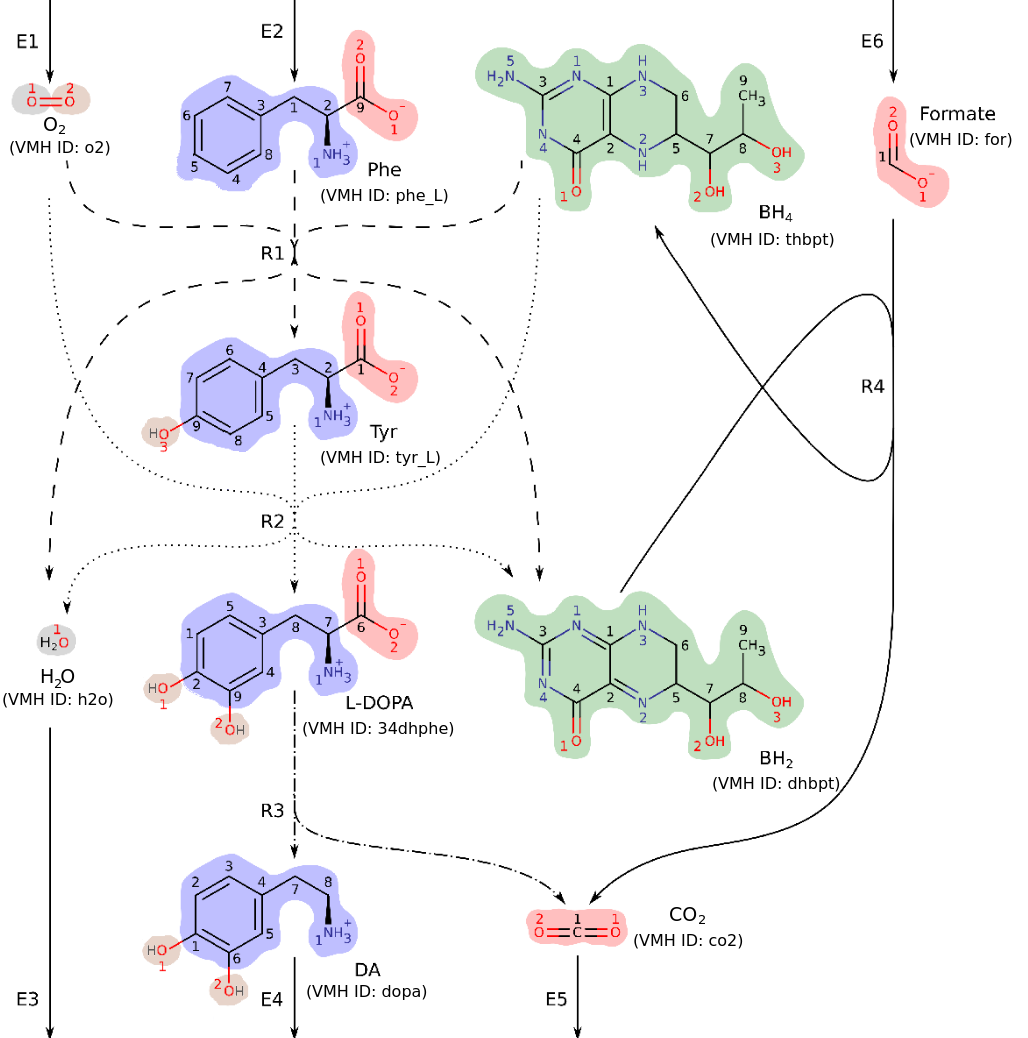

Figure 2: DAS: a small metabolic network consisting of reactions in the human dopamine synthesis pathway [2]. Atoms belonging to the same conserved moiety have identically coloured backgrounds.

## MATERIALS

To atom map reactions it is required to have Java version 8. To standardise chemical reaction is needed to download JChem from ChemAxon with its respective license

## Section 1 Reactions atom mappings

initCobraToolbox

Atom mappings for the internal reactions of a metabolic network reconstruction are performed by the function `obtainAtomMappingsRDT`. The main inputs are a COBRA model structure and a directory containing the molecular structures in MDL MOL format. For this example, the atom mappings are generated based on the molecular structures contained in cobratoolbox/tutorials/moieties/data/molFiles (`molFileDir`), the reconstructed DAS network without hydrogen atoms (`model`) and using the RDT algorithm.

load(['data' filesep 'subDas.mat']) % The subnetwork from the dopamine synthesis network
molFileDir = ['data' filesep 'molFiles']; % Metabolites chemical structures

The function `obtainAtomMappingsRDT `generates 4 different directories containing the atom mapped reactions in MDL RXN format, images of the atom mapped reactions, additional data for the atom mapped reactions (SMILES,  and product and reactant indexes) and unmapped MDL RXN files. Variable `rxnDir `indicates the directory where the folders will be generated (by default the function assigns the current directory).

outputDir = [pwd filesep 'output'];

For some reactions, the RDT algorithm cannot compute the atom mappings (for a large reaction is generated an MDL RXN v3000 which is not compatible with the RDT algorithm). Therefore, is necessary to assign a maximum time of processing `maxTime` (by default the function assign 30 minutes as a maximum time for computing an atom mapping for a reaction).

maxTime = 1800;

The function `obtainAtomMappingsRDT` generates atom mapped reactions in a canonical format but it is **REQUIRED** to have a Chemaxon license installed. However, the reactions can be atom mapped without being standardised. The variable `isChemaxonInstalled` contains a logical value defined by the user if the license is installed or not.

isChemaxonInstalled = false; % Change to "true" if Chemaxon is not installed

## TIMING

The time to compute atom mappings for metabolic reactions depends on the size of the genome-scale model and the size of the molecules in the reactions. This example may take ~1 min or less if `isChemaxonInstalled = false.`

tic
standardisedRxns = obtainAtomMappingsRDT(model, molFileDir, outputDir, maxTime, ...
                                         isChemaxonInstalled);
toc

As output, it is generated a list of atom mapped mass balanced reactions (`standardisedRxns`).

## Visualising results

The directory images contain a graphical representation of the atom mapped reactions. They show the bijection between atoms and each of the metabolite pools are coloured for an easy visualisation. Figure 3 shows the atom mapped reaction to produce dopamine and ${\text{CO}}_2$ from L-DOPA.

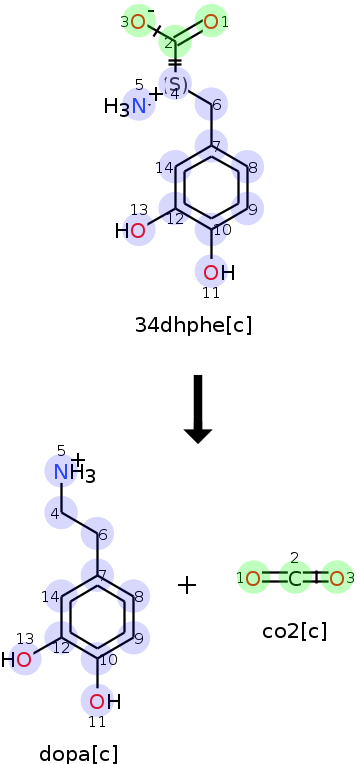

Figure 3: Reaction 3-hydroxy-L-tyrosine carboxy-lyase atom mapped (VMH ID: 3HLYCL) here represented as R3. Images generated by RDT algorithm, also shows where a reaction centre occur.

The directory rxnFiles contains for all atom mapped reactions a corresponding MDL RXN file. On them is contained the information of the chemical reaction. Line 2 contains the name of the reaction, the line 4 the chemical formula and line 5 the number of substrates and products. After the line 5, it is described the information of each of the molecules after the identifier $MOL. The header is in the first four lines where is found the name of the metabolite, its InChI key (if the metabolite does not contain an R group) and the number of atoms and bonds. In the atom block, is indicated the coordinates, element, charge and atom mapping number for each of the atoms and finally, the bond block connects all the atoms in the metabolite.

regexp(fileread([outputDir filesep 'atomMapped' filesep 'R3.rxn']), '\n', 'split')'

The last directory contains the TXT information of the reaction including the SMILES format which holds a canonical format of the reaction, the reactant input atom index and the product input atom index.

regexp(fileread([outputDir filesep 'txtData' filesep 'R3.txt']), '\n', 'split')'

## Section 2 Identifying conserved metabolic moieties

    A conserved moiety is a group of atoms within molecules connected by reactions, that follow identical paths through a metabolic network and therefore, its amount remains constant (Figure 4). Representative examples from energy metabolism include the AMP and NAD moieties. With the set of atom mappings for a metabolic network the set of linearly independent conserved moieties for the metabolic network can be identified, each of which corresponds to a particular identifiable molecular substructure [5].

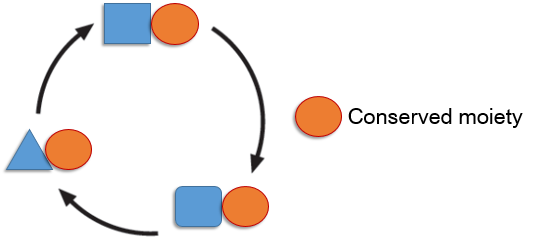

Figure 4: A graphical representation of a conserved moiety

In this section, we will identify conserved moieties in a subnetwork of the dopamine synthesis network DAS (Figure 2) by graph theoretical analysis of its atom transition network. The method is described in [5]. This section consists of two parts. Part 1 covers basic usage of the code. Part 2 covers decomposition of a composite moiety resulting from variable atom mappings between the reoccurring metabolite pair $O_2$ and $H_2 O$.

## Part 1: Identify conserved moieties in DAS

**Step 1: Generate an atom transition network for DAS based on atom mappings for internal (mass and charge balanced) reactions.**

The atom transition network is generated based on the reconstructed DAS network (`model`) and atom mappings for internal reactions, obtained in the previous section (`atomMappedDir`) and predicted with the RDT algorithm [3].

if ~isChemaxonInstalled
    copyfile('data/atomMapped',[outputDir filesep 'atomMapped'])
end    
atomMappedDir = [outputDir filesep 'atomMapped'];
ATN = buildAtomTransitionNetwork(model, atomMappedDir);

The output variable (`ATN`) is a Matlab structure with several fields. `ATN.A` is the incidence matrix of the directed graph representing the atom transition network. Each row represents a particular atom in one of the 11 DAS metabolites. `ATN.mets` indicates which metabolite in DAS each atom belongs to. To find rows of `ATN.A `corresponding to atoms in ${CO}_2$, run

ico2 = find(ismember(ATN.mets, 'co2[c]'))'

The order of atoms in `ATN.A` matches their order in MDL MOL files encoding metabolite structures (Figure 6), e.g., `ATN.A`(90,:) is the row corresponding to the second oxygen atom (number 3 in Figure 5).

Figure 5: Rows for ${CO}_2$ atoms in `ATN.A` are ordered as shown.

`ATN.elements` contains the element symbols of atoms, e.g.,

ATN.elements{90}

Each column of `ATN.A` represents a particular atom transition in one of the four internal reactions in DAS. Reaction identifiers of atom transitions are given in `ATN.rxns`. To find all atom transitions that involve ${\text{CO}}_2$ atoms, run

tco2 = find(any(ATN.A(ico2,:), 1))
ATN.rxns(tco2)'

i.e., three atom transitions in each of the reactions R3 and R4 involve atoms in ${\text{CO}}_2$. To find atoms connected to ${\text{CO}}_2$ atoms via these atom transitions, run

cco2 = find(any(ATN.A(:, tco2) < 0,2));
ATN.mets(cco2)'

i.e., ${\text{CO}}_2$ atoms are connected to atoms in the metabolites L-DOPA (VMH ID: 34dhphe) and formate (VMH ID: for).

**Step 2: Identify conserved moieties in DAS by graph theoretical analysis of the atom transition network generated in Step 1.**

tic
[L,Lambda,moietyFormulas,moieties2mets,moieties2vectors,atoms2moieties] = ...
    identifyConservedMoieties(model, ATN);
t = toc;
fprintf('Computation time: %.1e s\n\n', t); % Print computation time

This function outputs the moiety matrix (`L`), the moiety supergraph (`Lambda`), the chemical formulas of moieties (`moietyFormulas`), and three vectors that map between the various inputs and outputs. The 10×5 moiety matrix `L` has a row for each metabolite and a column for each conserved moiety in DAS. Each column is a moiety vector, with elements corresponding to the number of instances of a conserved moiety in each metabolite. To find the number of instances of moiety 2 in L-DOPA, run

iLDOPA = find(ismember(model.mets, '34dhphe[c]'))
full(L(iLDOPA, 2))

i.e., L-DOPA contains one instance of moiety 2.

The 19×17 moiety supergraph (`Lambda`) contains the graphs of all seven conserved moieties in DAS (Figure 6).

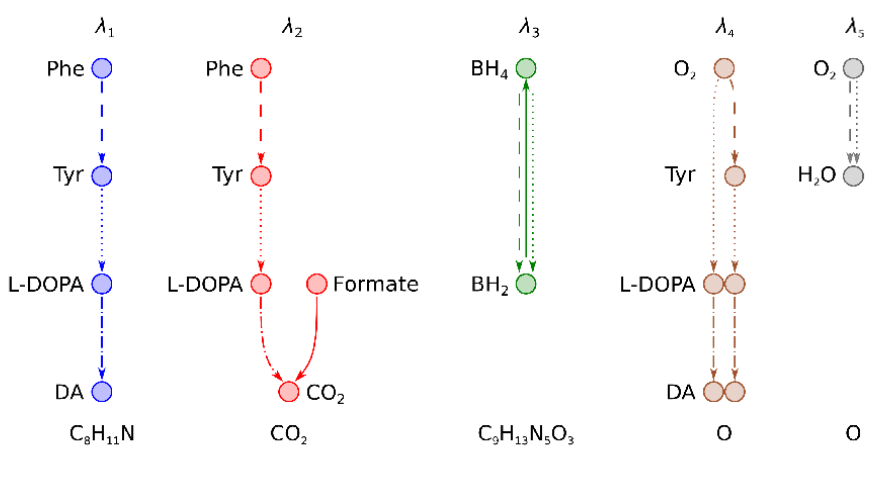

Figure 6: Graphs of the five conserved moieties in DAS. Each node represents an instance of a conserved moiety in a particular metabolite. Each directed edge represents conservation of a moiety between two metabolites. The chemical formula of each moiety is given below its graph.

Each row of Lambda represents a single instance of a conserved moiety in a particular metabolite. The vector moieties2vectors maps between the rows of Lambda and the columns of L. To obtain the incidence matrix of a particular moiety graph, e.g., λ2 in Figure 6, run

i2 = find(moieties2vectors == 2);
c2 = find(any(Lambda(i2, :)));
lambda2 = full(Lambda(i2, c2))

The vector `moieties2mets` maps the rows of Lambda to metabolite indices in the DAS reconstruction (`model`). To find metabolites containing instances of moiety 2, run

m2 = moieties2mets(i2);
mets2 = model.mets(m2)'

The chemical formula of moiety 2 is given by,

moietyFormulas{2}

Finally, the vector atoms2moieties maps each atom in the atom transition network for DAS to a particular instance of a conserved moiety. To find atoms in L-DOPA that belong to moiety 2, run

find(ismember(atoms2moieties, i2) & ismember(ATN.mets, '34dhphe[c]'))'

**Step 3: Classify moieties**

types = classifyMoieties(L, model.S)

The internal moiety (λ3 in Fig. 3) is conserved in both the open and closed DAS network, whereas the transitive and integrative moieties are only conserved in the closed network [6].

## Part 2: Effects of variable atom mappings between reoccurring metabolite pairs

Here, we will again identify conserved moieties in DAS but with a slightly different set of atom mappings (Figure 7). The different atom mappings give rise to a different atom transition network with a different set of conserved moieties. In particular, it contains a single composite moiety, λ8 in Figure 4, in place of the two moieties λ4 and λ5 in Figure 3. The composite moiety is the result of variable atom mappings between the reoccurring metabolite pair O2 and H2O in reactions R1 and R2.

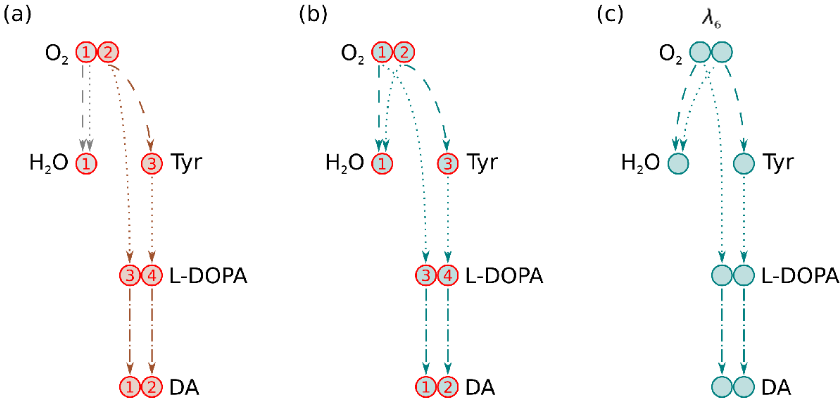

Figure 7: (a) Oxygen atom transitions used in Part 1. Oxygen atom 1 in O2 maps to the oxygen atom in H2O in both R1 and R2. These atom transitions contain two separate moieties, with two disconnected moiety graphs (λ4 and λ5 in Figure 6), and two linearly independent moiety vectors (L(:,4) and L(:,5)). (b) Oxygen atom transitions used in Part 2. A different oxygen atom maps from O2 to H2O in R1 than in R2. These atom transitions contain only one composite moiety. (c) The composite moiety graph arising from the oxygen atom transitions in (b).

**Step 1: Identify conserved moieties with the alternative set of atom mappings.**

% Create an alternative MDL RXN file
R2rxn = regexp(fileread([outputDir filesep 'atomMapped' filesep 'R2.rxn']), '\n', 'split')';
R2rxn{2} = 'alternativeR2';
R2rxn{135}(62:63) = '18';
R2rxn{151}(62:63) = '19';
fid2 = fopen([outputDir filesep 'atomMapped' filesep 'alternativeR2.rxn'], 'w');
fprintf(fid2, '%s\n', R2rxn{:});
fclose(fid2);

% Create an alternative DAS model
alternativeModel = model;
alternativeModel.rxns{2} = 'alternativeR2';

% Identify conserved moieties
ATN = buildAtomTransitionNetwork(alternativeModel, atomMappedDir);
[L,Lambda,moietyFormulas,moieties2mets,moieties2vectors,atoms2moieties] = ...
    identifyConservedMoieties(alternativeModel, ATN);

**Step 2: Decompose the composite moiety vector**

First, extract the internal stoichiometric matrix for DAS, by running

rbool = ismember(alternativeModel.rxns, ATN.rxns);
mbool = any(alternativeModel.S(:,rbool), 2);
N = alternativeModel.S(mbool, rbool);

To decompose the moiety matrix computed in Step 1, run

changeCobraSolver('gurobi6', 'milp');
D = decomposeMoietyVectors(L, N);

Note that you can use any MILP solver that is supported by the COBRA toolbox. The decomposed moiety matrix D is identical to the original moiety matrix computed in Part 1. Moiety vectors D(:,4) and D(:,5) are the linearly independent components of the composite moiety vector L(:,4) above.

full(D(:,[4 5])')

One disadvantage of decomposing moiety vectors is that it is difficult to keep track of which atoms belong to the decomposed moieties. We can, however, estimate the chemical formulas of the decomposed moieties using the elemental matrix for DAS. The elemental matrix is a numerical representation of the chemical formulas of metabolites in DAS.

[E,elements] = constructElementalMatrix(alternativeModel.metFormulas,...
    alternativeModel.metCharges);
decomposedMoietyFormulas = estimateMoietyFormulas(D, E, elements);
decomposedMoietyFormulas([4 5])'

i.e., each decomposed moiety contains an oxygen atom.

## References

[1] Haraldsdóttir, H.S., Thiele, I., Fleming, R.M.: Comparative evaluation of open source software for mapping between metabolite identifiers in metabolic network reconstructions: application to Recon 2. Journal of cheminformatics 6(1), 2 (2014).

[2] Elizabeth Brunk, Swagatika Sahoo, Daniel C. Zielinski, Ali Altunkaya, Andreas Dräger, Nathan Mih, Andreas Prlić, Anand Sastry, German A. Preciat Gonzalez, Anna D. Danielsdottir, Alberto Noronha, Maike K. Aurich, Peter W. Rose, Stephen K. Burley, Ronan M.T. Fleming, Jens Nielsen, Ines Thiele, Bernhard O. Palsson. Recon 3D: A Three-Dimensional View of Human Metabolism and Disease. Submited

[3] Rahman, S.A., Torrance, G., Baldacci, L., Cuesta, S.M., Fenninger, F., Gopal, N., Choudhary, S., May, J.W., Holliday, G.L., Steinbeck, C., Thornton, J.M.: Reaction Decoder Tool (RDT): extracting features from chemical reactions.  Bioinformatics 32(13), 2065–2066 (2016).

[4] German A. Preciat Gonzalez, Lemmer El Assal, Alberto Noronha, Ines Thiele, Hulda S. Haraldsdóttir, Ronan M.T. Fleming. Comparative evaluation of atom mapping algorithms for balanced metabolic reactions: application to Recon 3D. J Cheminform. 2017.

[5] Hulda S. Haraldsdóttir and Ronan M. T. Fleming. Identification of conserved moieties in metabolic networks by graph theoretical analysis of atom transition networks. PLOS Computational Biology, 12(11): e1004999, 2016.

[6] Iman Famili and B. Ø. Palsson. The convex basis of the left null space of the stoichiometric matrix leads to the definition of metabolically meaningful pools. Biophysical Journal, 85(1):16–26, 2003.